# Sudoku.

Se desarrolla un sistema de visión que resuelva Sudokus, capaz de detectarlos mediante la webcam o por la cámara del teléfono móvil. Se puede suponer que frente a la cámara se encuentra un único Sudoku estandar de 9x9 números, donde se mostrará en pantalla la imagen original, y la imagen con las posiciones con los números faltantes.

Autores: Ricardo Camacho Díaz - Cano

Pedro Antonio Estévez Pérez

Alberto García - Fogeda Gómez.

## Carga de la Imagen.

Se realiza un borrado del espacio del trabajo y se cierran todas las ventanas activas para evitar que el programa pueda entrar en conflicto.

clear, clc, close all;

En primer lugar, se carga el sudoku, para ello se da tres posibilidades, mediante la webcam del propio ordenador, la camara del teléfono movil y de forma manual. Otra posibilidad muy viable es la utilizacion de una aplicación externa de escaneo, como camscanner, que realiza un preprocesado muy bueno sobre la imagen y posteriormente se pasa dicha imagen por el metodo manual.

fprintf('Opciones para detectar el Sudoku: \n');

Opciones para detectar el Sudoku: 


fprintf('1. Webcam. \n');

1. Webcam. 


fprintf('2. Cámara del telefono movil. \n');

2. Cámara del telefono movil. 


fprintf('3. Manual. \n');

3. Manual. 


Se pide al usuario que introduzca la opción tantas veces posibles hasta que se introduzca un valor valido.

opc = 0;
while(opc < 1 || opc > 3)
    opc = input('Introduce la opcion: ');
end

Se despliega un menu que contengan las diferetes opciones, donde en cada opción se realizará la llamada a la función correspondiente. Todas las funciones tienen en común que devuelven una imagen como argumento de salida, donde se encuentra el sudoku. 

if (opc == 1)
    imag = webcamForm;
elseif (opc == 2)
    IP = 'http://192.168.1.172:4747/video';
    imag = mobileForm(IP);
else
    imag = manualForm;
end

Pulse cualquier tecla para capturar la imagen.

## Preprocesado de la Imagen.

Se crea una copia de la imagen en escala de grises.

grayscale = rgb2gray(imag);

Se da la opción al usuario de poder definir la región de interés (ROI), debido a que en la mayoria de casos el sudoku aparece en un entorno.

fprintf('Desea seleccionar la Region de Interes para mejorar la captacion del Sudoku: \n1. Si \n2. No \n');

Desea seleccionar la Region de Interes para mejorar la captacion del Sudoku: 
1. Si 
2. No 


Se pide al usuario que introduzca la opción tantas veces posibles hasta que se introduzca un valor válido.

opc = 0;
while(opc < 1 || opc > 2)
    opc = input('Introduce la opcion: ');
end

En el caso de elegir definir la region de interes, se llama a la funcion selectROI que devuelva la imagen binarizada. En caso contrario, se realiza un ajuste del contraste de la imagen, para detallar el contorno y los numeros, posteriormente se realiza una erosion y se reconstruye combinandola con la imagen ajustada, dando como resultado una imagen donde se resalta tanto el contorno como los numeros y se realiza un binarizado adaptativo sobre la imagen.

if(opc == 1)
    BW = selectROI(grayscale);
else
    imagadjusted = imadjust(grayscale);
    
    marker = imerode(imagadjusted, strel('line',4,0));
    
    imagclean = imreconstruct(marker, imagadjusted);
    
    BW = imbinarize(imagclean,'adaptive','ForegroundPolarity','dark','Sensitivity',0.4);
end

A continuación, se trata la imagen para obtener el contorno del sudoku e identificar los numeros.

Se crea otra imagen binaria, que es el complemento de BW y se determina la posicion del sudoku dentro de la imagen.

BW2 = bwareafilt(imcomplement(BW),1,'largest');

label = bwlabel(BW2);

[row,col] = find(label==1);

Una vez conocidas las coordenadas del sudoku dentro de la imagen, se procede a recortar las imágenes originales, tanto BW como BW2 y se guardan en una copia.

BW3 = BW(min(row):max(row),min(col):max(col));

BW4 = BW2(min(row):max(row),min(col):max(col));

Se rota las imagenes, donde esta funcion es opcional.

% BW3= rotateImg(BW3);

Finalmente se restan las imágenes BW4 y BW3, dando como resultado los números. Se recuerda que BW4 es la complementada de BW3 por lo que se vuelve a invertir.

BW5 = logical(imcomplement(BW3)-BW4);

## Identificación del Sudoku.

Una vez obtenidas las imágenes tanto de los números como del contorno del sudoku.

Se calculan los píxeles de las casillas a partir del tamaño de BW5.

[ancho,alto] = size(BW5);     
ancho_casilla = floor(ancho/9);      
alto_casilla = floor(alto/9);  

Se inicializa la matriz asociada al sudoku donde se almacenarán los números iniciales. Posteriormente se resolverá el sudoku en dicha matriz.

sudokuMatrix = [];

Posteriormente se procede a indentificar los numeros.

Xi = 1;
for f = 1:9
    Yi = 1;
    for c = 1:9
        BW6 = BW5(Xi:f*alto_casilla,Yi:c*ancho_casilla);
        Yi = c*ancho_casilla;   %salto a la siguiente casilla.
        % OCR para cada celda
        l = ocr(BW6, 'CharacterSet', '0123456789', 'TextLayout','Block');
         T = double(l.Text);
         lenT = size(T);
           if (lenT(2) ~= 0)
            switch T(1)
                case 49
                    sudokuMatrix(f,c) = 1; 
                case 50
                    sudokuMatrix(f,c) = 2;
                case 51
                    sudokuMatrix(f,c) = 3;
                case 52
                    sudokuMatrix(f,c) = 4;
                case 53
                    sudokuMatrix(f,c) = 5;
                case 54
                    sudokuMatrix(f,c) = 6;
                case 55
                    sudokuMatrix(f,c) = 7;
                case 56
                    sudokuMatrix(f,c) = 8;
                case 57 
                    sudokuMatrix(f,c) = 9;
                otherwise
                    sudokuMatrix(f,c) = 0;
             end
            end
          if (lenT(2)==0)
               sudokuMatrix(f,c) = 0;
          end
    end
    Xi = f*alto_casilla;    % Salto a la siguiente fila
end

Ya tenemos totalmente identificada la matriz. Ahora se adapta para poder introducirla en la toolbox de sudokuEngine, que resolverá el sudoku. Para ello se transforma tantas filas como numeros haya, y las dos primeras columnas son coordenadas y la tercera el valor de esa posicion.

flag = 0;
for i=1:9
    for k=1:9
        if (sudokuMatrix(i,k) > 0)
            c = [i,k,sudokuMatrix(i,k)];
            flag = 1; 
           break
        end
    end
    if(flag == 1)
        break;
    end
end
 
for i=1:9
    for k=1:9
        if sudokuMatrix(i,k)>0
            b = [i,k,sudokuMatrix(i,k)];
            c = [b;c];
        end
    end
end

Una vez construida la matriz del sudoku, se procede a dibujar el sudoku original, mediante la funcion auxiliar 'drawSudoku'.

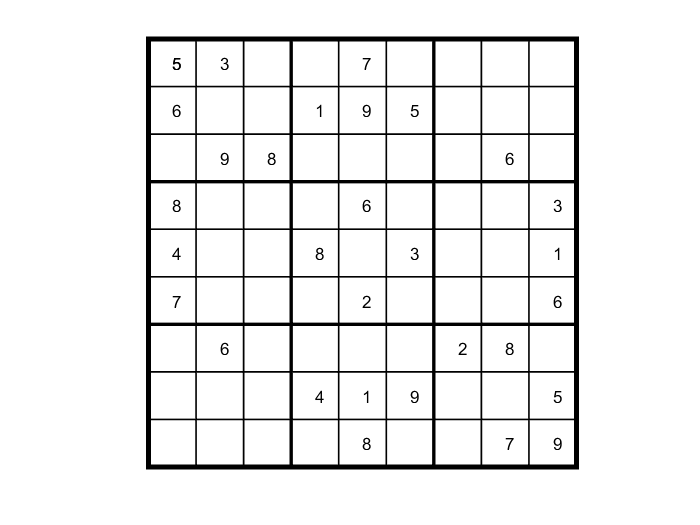

drawSudoku(c);

## Resolución del Sudoku.

Para resolver el sudoku se realiza llamando a la toolbox de matlab sudokuEngine 

S=sudokuEngine(c);

LP:                Optimal objective value is 29565.000000.                                         


Optimal solution found.

Intlinprog stopped at the root node because the objective value is within a gap tolerance of the optimal
value, options.AbsoluteGapTolerance = 0 (the default value). The intcon variables are
integer within tolerance, options.IntegerTolerance = 1e-05 (the default value).



Se muestra el resultado final.

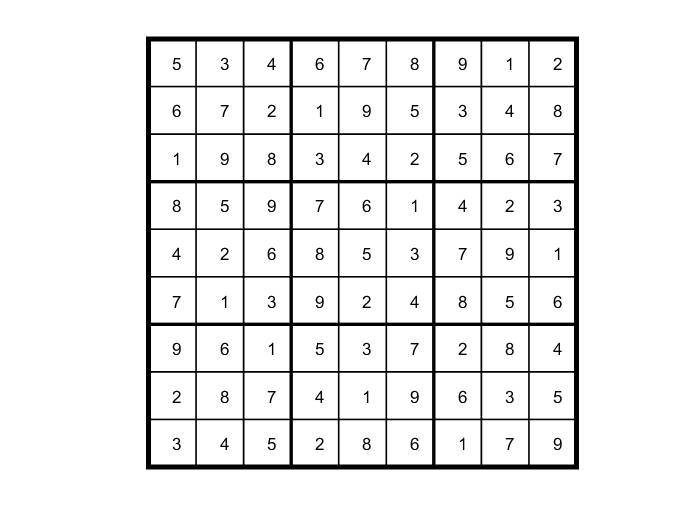

drawSudoku(S);

## Funciones Auxiliares.

selectRoi es una funcion que selecciona la region de interes de la imagen. .

function [imag]=selectROI(grayscale)

Se muestra la imagen y se define la region de interes

imshow(grayscale)
roi = images.roi.Polygon('StripeColor','m');
draw(roi)

Se crea una máscara con la región de interés y se pasa a formato uint8.

B = createMask(roi);
B = im2uint8(B);

Se aplica la máscara a la imagen original, donde los valores que se encuentran fuera se definen como negros.

for i=1:size(grayscale,1)
    for j=1:size(grayscale,2)
        if (B(i,j)~=255)
            grayscale(i,j)=0;
        end
    end
end

Se realiza un ajuste del contraste de la imagen, para detallar el contorno y los numeros, gracias a que la region que no es de interes se ha definido como negra, se aumenta el contraste del sudoku. Posteriormente se realiza una erosion y se reconstruye combinandola con la imagen ajustada, dando como resultado una imagen donde se resalta tanto el contorno como los numeros y se realiza un binarizado adaptativo sobre la imagen.

imagadjusted = imadjust(grayscale);

marker = imerode(imagadjusted, strel('line',4,0));

imagclean = imreconstruct(marker, imagadjusted);

BW=imbinarize(imagclean,'adaptive','ForegroundPolarity','dark','Sensitivity',0.4);


Se redefinen las regiones fuera de la region de interes como blancos sobre la imagen binarizada, para poder identificar el sudoku con mejor precision y se devuelve como argumento de salida.


for i=1:size(BW,1)
    for j=1:size(BW,2)
        if (B(i,j)~=255)
            BW(i,j)=255;
        end
    end
end

imag=BW;

end

rotateImg es una funcion que muestra un menu para poder girar la imagen tanto a la derecha como a la izquierda, el cual se rota tantas veces como quiera el usuario, ya que en cada iteracion se rota 1º.

Esta funcion es opcional, ya que al obtener una imagen que no esta bien cuadrada, se rota para cuadrarla correctamente pero los resultados no son los esperados ya que se deforman tanto los numeros como los rectangulos, no identificando correctamente tanto su valor como su posicion. Solo funciona correctamete en casos muy concretos.

function [img] = rotateImg (BW3)
fprintf('Quiere realizar una rotacion sobre la imagen: \n');
fprintf('1. No. \n');
fprintf('2. Hacia la derecha. \n');
fprintf('3. Hacia la izquierda. \n');

Se pide al usuario que introduzca la opción tantas veces posibles hasta que se introduzca un valor valido.

opc = 0;
while(opc < 1 || opc > 3)
    opc = input('Introduce la opcion: ');
end

Se realiza la rotacion de un 1º en el sentido que se indica y se devuelve como argumento de salida.

if (opc==2)
    cont=0;
    while (cont~=1)
        BW3=imrotate(BW3,1,'bilinear','crop');
        figure(1);
        imshow(BW3);
        cont=input('Desea continuar: 1. Si     '); 
    end
elseif (opc==3)
        cont=0;
    while (cont~=1)
        BW3=imrotate(BW3,-1,'bilinear','crop');
        figure(1);
        imshow(BW3);
        cont=input('Desea continuar: 1. Si.    ');
    end
end
img=BW3;
end

webcamForm es una función que obtiene una imagen de la webcam donde se encuentra el sudoku.

function [img] = webcamForm()

Se muestra el numero de webcams disponibles. 

En el caso de que solo exista una webcam, se selecciona por defecto. En el caso de que tenga mas de una se despliga un menu de selección.

webcamlist

if (size(webcamlist,1) > 1)
    sel = 0;
    while(sel < 1 || sel > size(webcamlist,1))
        sel = input('Introduce que webcam desea conectar: ');
    end
    cam = webcam(sel);
else
    cam = webcam;
end

Por defecto Matlab obtiene las imagenes en las máxima resolución por lo que no es necesario modificar los parametros.

Se realiza una previsualización de la webcam y para tomar la imagen, se realiza poniendo en pausa el programa y cuando se pulse cualquier tecla se ejecuta la linea de código que obtiene la imagen y se devuelve como parametro de salida.

preview(cam)

fprintf('Pulse cualquier tecla para capturar la imagen.');
pause;

img = snapshot(cam);

end

Para capturar imágenes utilizando la cámara del móvil hay que descargar cualquier aplicación IP Webcam de la android Store. Las que nosotros hemos probado y que funcionan mejor son DroidCam e IP Webcam. Una vez realizada la cofiguración inicial de la app, ésta proporcionará una dirección IP, que será la que haya que introducir arriba en el código. Al ejecutarlo, Matlab lee la feed de esa IP mostrando la imagen y haciendo una foto al presionar una tecla.

function [img] = mobileForm(IP)

Se construye el url con la IP y el formato de la imagen.

cam = ipcam(IP);

Al igual que para la webcam, la toma de la imagen se realiza poniendo en pausa el programa y cuando se pulse cualquier tecla, el ordenador lee la fotografia que muestra el dispositivo movil y la devuelve como argumento de salida.

preview(cam);
fprintf('Pulse cualquier tecla para capturar la imagen.');
pause;

img = snapshot(cam);

end

manualForm es una funcion que obtiene la imagen de forma manual, donde se introduce el nombre de la imagen entre comillas(' ') para poder ser leida posteriormente.

function [img] = manualForm()

imagen = input('Introduce el nombre de la imagen: ');

img = imread(imagen);

end

drawSudoku es una función que se encarga de dibujar el tablero del Sudoku.

function [] = drawSudoku (B)

En primer lugar se dibuja el sudoku vacio, mediante rectangulos en diferentes posiciones.

figure;hold on;axis off;axis equal % Preparado para dibujar
rectangle('Position',[0 0 9 9],'LineWidth',3,'Clipping','off') % Borde exterior
rectangle('Position',[3,0,3,9],'LineWidth',2) % lineas verticales superiores
rectangle('Position',[0,3,9,3],'LineWidth',2) % lineas horizontales superiores
rectangle('Position',[0,1,9,1],'LineWidth',1) % lineas horizontales inferiores
rectangle('Position',[0,4,9,1],'LineWidth',1)
rectangle('Position',[0,7,9,1],'LineWidth',1)
rectangle('Position',[1,0,1,9],'LineWidth',1) % lineas verticales inferiores
rectangle('Position',[4,0,1,9],'LineWidth',1)
rectangle('Position',[7,0,1,9],'LineWidth',1)

Se completan las celdas.

Las filas de B tienen la forma (i,j,k) donde i es la fila que cuenta desde la parte superior, j es la columna y k es la celda, es decir, el argumento de entradas son las posiciones de los diferentes numero y su valor. Para colocar las entradas en los cuadros, k es la distancia horizontal, 10-i es la distancia vertical y restamos 0.5 para centrar la pista en el cuadro.

Si B es una matriz de 9x9, se convierte primero en 3 columnas.

if size(B,2) == 9 % 9 columnas
    [SM,SN] = meshgrid(1:9); % i,j,k como entradas
    B = [SN(:),SM(:),B(:)]; % i,j,k columnas
end

for i = 1:size(B,1)
    text(B(i,2)-0.5,9.5-B(i,1),num2str(B(i,3)))
end

hold off

end

SudokuEngine es una función propietaria de Matlab que devuelve la solución del sudoku al introducirle la matriz con los números proporcionados.

function [S,eflag] = sudokuEngine(B)

Esta función establece las reglas para el Sudoku. Se lee en el rompecabezas expresado en la matriz B, llama a intlinprog para resolver el rompecabezas y devuelve la solución en la matriz S. La matriz B debe tener 3 columnas y al menos 17 filas (porque un rompecabezas Sudoku necesita al menos 17 entradas para ser único soluble). Los primeros dos elementos en cada fila son las coordenadas i, j de una pista, y el tercer elemento es su valor, un número entero de 1 a 9. Si B es una matriz de 9 por 9, la función primero la convierte en una de 3 columnas.

Copyright 2014 The MathWorks, Inc.

if isequal(size(B),[9,9]) % Matriz 9 x 9
    % Se convierto a matriz 81 x 3
    [SM,SN] = meshgrid(1:9); % se hace entradas i,j
    B = [SN(:),SM(:),B(:)]; % filas i, j, k
    % Se borran las filas en cero.
    [rrem,~] = find(B(:,3) == 0);
    B(rrem,:) = [];
end

if size(B,2) ~= 3 || length(size(B)) > 2
    error('The input matrix must be N-by-3 or 9-by-9')
end

if sum([any(B ~= round(B)),any(B < 1),any(B > 9)]) % enforces entries 1-9
    error('Entries must be integers from 1 to 9')
end

Las reglas del sudoku son: 

N = 9^3; % numero de variables independientes en x, una matriz de 9 por 9 por 9
M = 4*9^2; % numero de restricciones, ver la construcción de Aeq
Aeq = zeros(M,N); % asignar matriz de restricción de igualdad Aeq * x = beq
beq = ones(M,1); % asignar beq de vector constante
f = (1:N)'; % el objetivo puede ser cualquier cosa, pero tener una f no constante puede acelerar el solucionador
lb = zeros(9,9,9); % una matriz cero inicial
ub = lb+1; % matriz de límite superior para dar variables binarias

counter = 1;
for j = 1:9 % uno en cada fila
    for k = 1:9
        Astuff = lb; % se limpia Astuff
        Astuff(1:end,j,k) = 1; % una fila en Aeq * x = beq
        Aeq(counter,:) = Astuff(:)'; % poner a Astuff en una fila de Aeq
        counter = counter + 1;
    end
end

for i = 1:9 % uno en cada columna
    for k = 1:9
        Astuff = lb;
        Astuff(i,1:end,k) = 1;
        Aeq(counter,:) = Astuff(:)';
        counter = counter + 1;
    end
end

for U = 0:3:6 % uno en cada cuadrado.
    for V = 0:3:6
        for k = 1:9
            Astuff = lb;
            Astuff(U+(1:3),V+(1:3),k) = 1;
            Aeq(counter,:) = Astuff(:)';
            counter = counter + 1;
        end
    end
end

for i = 1:9 % uno en cada profundidad
    for j = 1:9
        Astuff = lb;
        Astuff(i,j,1:end) = 1;
        Aeq(counter,:) = Astuff(:)';
        counter = counter + 1;
    end
end

Ponga el acertijo particular en las restricciones

 Incluya las pistas iniciales en la matriz  | lb |  configurando las entradas correspondientes en 1. Esto obliga a la solución a tener | x (i, j, k) = 1 |.

for i = 1:size(B,1)
    lb(B(i,1),B(i,2),B(i,3)) = 1;
end

Resolver el rompecabezas

El problema de Sudoku está completo: las reglas están representadas en las matrices | Aeq | y | beq |, y las pistas son las que están en la matriz | lb |. Se resuelve el problema llamando a | intlinprog |. Se asegura de que el programa entero tenga todas las variables binarias estableciendo el argumento intcon en | 1: N |, con límites inferior y superior de 0 y 1.

intcon = 1:N;

[x,~,eflag] = intlinprog(f,intcon,[],[],Aeq,beq,lb,ub);


Convertir la solución a una forma utilizable

Para pasar de la solución x a una cuadrícula de Sudoku, simplemente sume los números en cada entrada $ (i, j) $, multiplicada por la profundidad a la que aparecen los números:

if eflag > 0 % Buena solucion
    x = reshape(x,9,9,9); % cambiar de nuevo a una matriz de 9 por 9 por 9
    x = round(x); % limpiar soluciones no enteras
    y = ones(size(x));
    for k = 2:9
        y(:,:,k) = k; % multiplicador para cada profundidad k
    end

    S = x.*y; % multiplica cada entrada por su profundidad
    S = sum(S,3); % S es 9 por 9 y contiene el rompecabezas resuelto
else
    S = [];
end
end